# Code 2: Analytical derivation of non-linearity due to uncertainty in measurement time

Here we show proof that a system's response can appear non-linear due to uncertainty in the time of measurements of the system's input. 

by Nithin Sivadas

**Note: Please do not share without Nithin's explicit permission. **

Updated: 7th Oct 2021; 6th Aug 2021; Dec 25th; Jan 5th

29 Dec 2021 - Added validation with Monte-Carlo method

25 Sep 2025 - Change the x-axis lim to 0-25 mV/m

outputFolder = 'H:\My Drive\Research\Projects\Paper 6\Draft\Version 5\Figures\Original\';
%outputFolder = 'G:\My Drive\Research\Projects\Paper 6\Draft\Version 4\NatCom\Figures\';

## Definitions

Here we attempt to develop an analytical/numerical solution for the conditional probability density of $X$ given $W$. As above, 


$$W = X(t+\Delta)$$



$$X \sim f_X(x)$$



$$\Delta \sim f_\Delta(\delta)$$


In our case, $f_X(x)$ is defined to be a lognormal function, and $f_{\Delta}(\delta)$is a gaussian distribution. More on this later. 

Assuming the process is stationary, and $X$ and $\Delta$ are independent, we get 

$f_W(w) = f_X(w)$       $\rightarrow$(eq.1)

A lognormal random variable $X$ can also be converted to a gaussian random variable $Z
$. 

Where, $Z \sim \phi(z,\mu_Z,\sigma_Z)$ and $Y = \log X$

Here,  $\phi(x,\mu,\sigma) = \frac{1}{\sqrt{2\pi}\sigma} e^{-\frac{(x-\mu)^2}{2\sigma^2 }}$  $$ \rightarrow$
$(eq.2), General normal distribution

phi = @(x,m,s) s.^-1.*(2.*pi).^-0.5.*(exp(-0.5*(s.^-1.*(x-m)).^2));

and $X(t)\sim f_X(x) = \frac{1}{x(t)}\phi(\log x(t), \mu_Z,\sigma_Z)$

fx = @(x,m,s) x.^-1.*phi(log(x),m,s);

$\mu_X, \sigma_X
$ are known, and are related to $\mu_Z, \sigma_Z
$ in the following manner

$\mu_Z = \log \Bigg( \frac{\mu_X^2}{\sqrt{\mu_X^2 + \sigma_X^2}} \Bigg)$$\rightarrow$ (eq.3)

$\sigma_Z = \sqrt{\log \Bigg( 1 + \frac{\sigma_X^2}{\mu_X^2} \Bigg)}$$\rightarrow$ (eq.4)

mz = @(m,s) log(m.^2.*(m.^2 + s.^2).^-0.5);
sz = @(m,s) (log(1+(s./m).^2)).^0.5;

$X(t)
$is autocorrelated to itself, and its autocorrelation coefficient is


$$\rho_X(\delta,k) = e^{-\frac{|\delta|}{k}}$$


$k
$** is the autocorrelation time constant**

rhox = @(d,k) exp(-abs(d)./k);

the corresponding autocorrelation of the normal random variable $Y
(t)$ is


$$\rho_Z(\delta,k) = \frac{1}{\sigma_Z^2}\log(1+\rho_X(\delta,k)[e^{\sigma_Z^2}-1])$$


rhoz = @(d,sz,k) sz.^-2.*log(1+rhox(d,k).*(exp(sz.^2)-1));

In addition, the random time delay follows a zero mean gaussian distribtion


$$f_\Delta(\delta) = \phi(\delta/\sigma_\delta)$$


fD = @(d,s) phi(d,0,s);

$\sigma_\delta

$** is a measure of the uncertainty in the random time delay **$\Delta
$

## Derivation

From eq.1 we can derive 

$f_{X|W}(x|w) = f_{W|X}(w|x) \frac{f_X(x)}{f_X(w)}$    $\rightarrow$(eq.5)

Also, 

$f_{W|X}(w|x) = \int_{-\infty}^{\infty} f_{ W | X, \Delta }(w|x, \delta ) f_{\Delta}( \delta) d \delta \ \ \ \rightarrow
 $(eq.6)

Now from eq.2 and bi-variate lognormal distribution, we get, 

$f_{ W | X, \Delta }(w|x, \delta )  =  \frac{1}{x_2} \phi \Big( \log w, \ 
\mu_{Z} + \rho_{Z}(\delta)[\log x - \mu_Y], \ 
\sigma_{Z} \sqrt{1-\rho_Z^2(\delta)} \Big) \rightarrow
$(eq.7)

fwgxd = @(w,x,d,mz,sz,k) w.^-1.*phi(log(w),mz+rhoz(d,sz,k).*(log(x)-mz),sz.*(1-(rhoz(d,sz,k)).^2).^0.5); % eq.7
fwgx = @(w,x,my,sz,k,sd) integral(@(d) fwgxd(w,x,d,my,sz,k).*fD(d,sd),-inf,inf,'ArrayValued',true); % eq.6

### Numerical Integration

Finally, from eq.5, eq.6, and eq.7, and taking the first moment of the distribution and normalizing it, we get 

$\langle X|W=w \rangle = \frac{\int_0^\infty xf_{X|W}(x|w) \mathrm{d}x}{\int_0^\infty f_{X|W}(x|w) \mathrm{d}x} $ $\rightarrow$ (eq.8) 

The conditional expectation of X|W, is the best estimate of $X$ we have given the erroneous measurement $W$. 

Since the integral is challenging to do analytically, we resort to numerical integration. 

Fxgw = @(w,x,mx,sx,k,sd) fwgx(w,x,mz(mx,sx),sz(mx,sx),k,sd).*fx(x,mz(mx,sx),sz(mx,sx))./(fx(w,mz(mx,sx),sz(mx,sx))); %eq.5
nFxgw = @(w,x,mx,sx,k,sd) Fxgw(w,x,mx,sx,k,sd)./integral(@(x) Fxgw(w,x,mx,sx,k,sd),0,inf,'ArrayValued',true); 
Exgw = @(w,mx,sx,k,sd) integral(@(x) x.*Fxgw(w,x,mx,sx,k,sd),0,inf,'ArrayValued',true);
nExgw = @(w,mx,sx,k,sd) Exgw(w,mx,sx,k,sd)./integral(@(x) Fxgw(w,x,mx,sx,k,sd),0,inf,'ArrayValued',true); %eq.8

## Likelihood function given a specific delay$F_{W|X,\Delta}(w|x,\delta)
$

Key point here is that $F_{W|X,\Delta}(w|x,\delta) = f(\delta/k,x)
$ , is a function of the ratio $\delta/k
$. This can be seen in eq.7, combined with the formula for $\rho_Z(\delta,k) 
$ and $\rho_X(\delta,k) $, which are both just functions of $\rho_Z(\delta/k) $ and $\rho_X(\delta/k) $. 

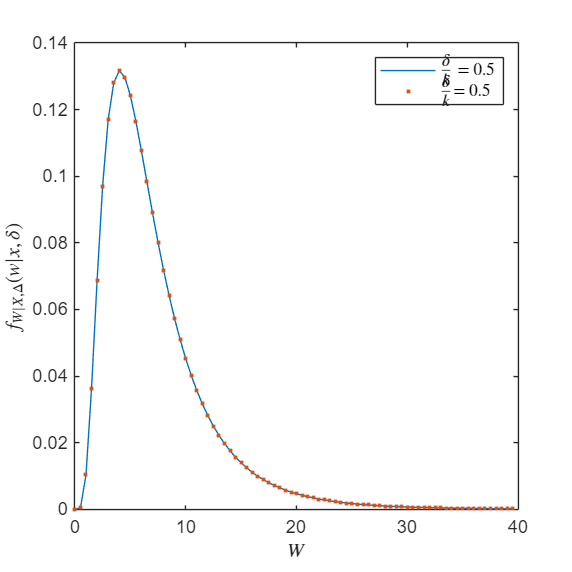

fig1=figure;
resize_figure(fig1,2*55,2*55);
% mx = -0.25; %1.125
% sx = 0.85; % 1.1488
mx = 1.12; % -0.2517
sx = 1.15; % 0.8516
xbin = 0.01:0.5:40;
d = 1;
k = 2;
plot(xbin,fwgxd(xbin,15,5,mz(mx,sx),sz(mx,sx),10));
hold on;
plot(xbin,fwgxd(xbin,15,d,mz(mx,sx),sz(mx,sx),k),'.');
set(gca,'XScale','linear');
xlabel('$W$','Interpreter','latex');
ylabel('$f_{W|X,\Delta}(w|x,\delta)$','Interpreter','latex');
legend('$\frac{\delta}{k}$ = 0.5',['$\frac{\delta}{k}$= ',num2str(d/k,2)],'Interpreter','latex');

## Likelihood function$F_{W|X}(w|x)
$

By integrating away $\delta
$, we get $F_{W|X}(w|x)
 = f(\sigma_{\delta}/k,x)
$ , is a function of the ratio $\sigma_\delta/k
$. This is a result of the integration in eq.6, which is challenging to do analytically. As a result it is surprising that it a function of the ratio $\sigma_\delta/k
$, which we call here the **effective temporal uncertainty**.  

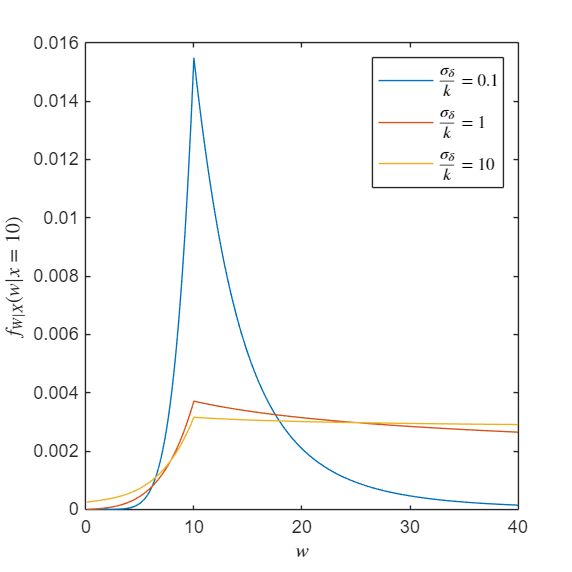

fig2=figure;
resize_figure(fig2,2*55,2*55);
% mx = -0.25;
% sx = 0.85;
xbin = 0.1:0.1:40;
ratio1 = 0.1;
ratio2 = 1; % k/sd
ratio3 = 10;
y1 = fwgx(10,xbin,mz(mx,sx),sz(mx,sx),1,ratio1);
y2 = fwgx(10,xbin,mz(mx,sx),sz(mx,sx),1,ratio2);
y3 = fwgx(10,xbin,mz(mx,sx),sz(mx,sx),1,ratio3);
plot(xbin,y1./trapz(y1)); % Note: we are plotting normalized pdfs 
hold on;
plot(xbin,y2./trapz(y2));
hold on;
plot(xbin,y3./trapz(y3));
xlabel('$w$','Interpreter',"latex");
ylabel('$f_{W|X}(w|x=10)$','Interpreter','latex')
legend(['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio1)], ...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio2)], ...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio3)],'Interpreter','latex');
set(gca,'XScale','linear');

## Posterior probability distribution$F_{X|W}(x|w)
$

From eq.5, eq.6, and eq.7, we $F_{X|W}(x|w)
 = f(\sigma_{\delta}/k,w)
$ , which also remains a function of the ratio $\sigma_\delta/k
$. As the **effective temporal uncertainty** decreases, the probability that $X
$ (a.k.a true value) is close to what is measured $W$increases. 

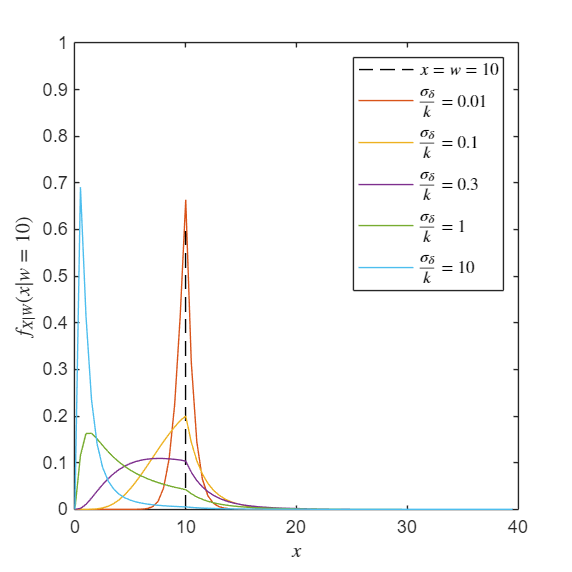

fig3=figure;
resize_figure(fig3,2*55,2*55);
% mx = -0.25;
% sx = 0.85;
xbin = 0.01:0.5:40;
ratio = 0.01; % sd/k
ratio1 = 0.1;
ratio2 = 0.3;
ratio3 = 1;
ratio4 = 10;
plot(10.*ones(1,10),linspace(0,0.6,10),'--k');
hold on;
plot(xbin,nFxgw(10,xbin,mx,sx,1,ratio));
hold on;
plot(xbin,nFxgw(10,xbin,mx,sx,1,ratio1));
hold on;
plot(xbin,nFxgw(10,xbin,mx,sx,1,ratio2));
hold on;
plot(xbin,nFxgw(10,xbin,mx,sx,1,ratio3));
hold on;
plot(xbin,nFxgw(10,xbin,mx,sx,1,ratio4));
xlabel('$x$','Interpreter',"latex");
ylabel('$f_{X|W}(x|w=10)$','Interpreter','latex')
legend( '$x=w=10$',...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio)],...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio1)], ...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio2)], ...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio3)], ...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio4)], ...
    'Interpreter','latex');
set(gca,'XScale','linear');
xlim([0 40])
ylim([0 1])

wbin = 0.01:0.5:40;
xbin = 0.01:0.5:40;
Z = zeros(length(wbin),length(xbin));
for i = 1:length(wbin)
    Z(i,:)=nFxgw(wbin(i),xbin,mx,sx,1,ratio2);
end

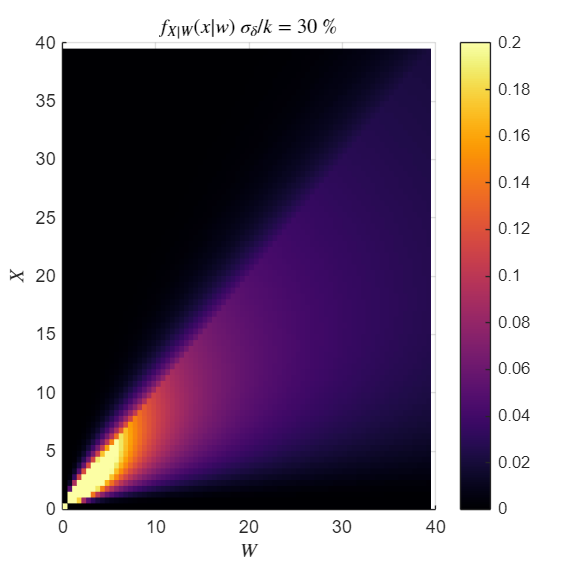

fig4=figure;
resize_figure(fig4,2*55,2*55);
colormap('inferno');
surf(wbin,xbin,Z','EdgeColor','none');
view(2);
xlabel('$W$','Interpreter','latex');
ylabel('$X$','Interpreter','latex');
colorbar();
set(gca,'ColorScale','linear');
caxis([0 0.2]);
title(['$f_{X|W}(x|w)$ $\sigma_\delta/k = $',num2str(100*ratio2),' \%'],'Interpreter','latex');
xlim([0,40]);
ylim([0,40]);

## Result: Non-linearity in $$\langle X|W \rangle$$increases with effective temporal uncertainty $\sigma_\delta /k$

The figure shows, non-linearity increasing with effective temporal uncertainty. This proves the claim that "uncertainty in measurement time can create a perception of non-linear bias in the systems response", if $X
$ drives some output $Y_{out}
$, and we regress $Y_{out}
$ with $X$. Furthermore, if $X$ propagates through a system, and$W=X(t+\Delta)
$ is read as output at the other end, then this system's response can apprear to be non-linear - especially if there is more than $$10\%$$ effective temporal uncertainty. For a 30% temporal uncertainty, the true regression function is at least 400% higher than when the function saturates at the highest value of the erroneous input $W=40$ units. 

wbin = 1:2:40;
xT = zeros(1,length(wbin));
xT1 = nExgw(wbin,mx,sx,100,1);
xT2 = nExgw(wbin,mx,sx,10,1);
xT3 = nExgw(wbin,mx,sx,3,1);
xT4 = nExgw(wbin,mx,sx,1,1);
xT5 = nExgw(wbin,mx,sx,0.5,1);

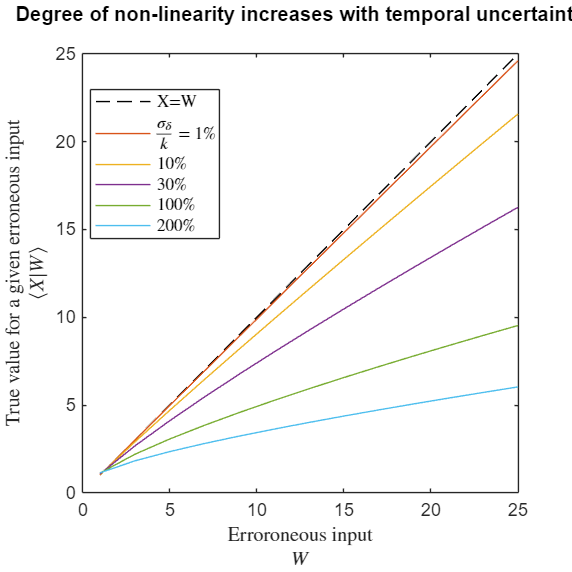

figM4=figure;
resize_figure(figM4,2*55,2*55);
plot(wbin,wbin,'--k');
hold on;
plot(wbin,xT1);
hold on;
plot(wbin,xT2);
hold on;
plot(wbin,xT3);
hold on;
plot(wbin,xT4);
hold on;
plot(wbin,xT5);
title('Degree of non-linearity increases with temporal uncertainty',' ','Interpreter','none')
xlabel({'Erroroneous input','$W$'},'Interpreter','Latex');
ylabel({'True value for a given erroneous input','$\langle X|W \rangle$'},'Interpreter','Latex');
legend(['X=W'],...
    ['$\frac{\sigma_{\delta}}{k}$ = $1\%$'], ...
    ['$10\%$'], ...
    ['$30\%$'], ...
    ['$100\%$'], ...
    ['$200\%$'], ...
    'Interpreter','latex','Location','Best');
xlim([0,25]);
ylim([0,25]);

%export_fig([outputFolder,'Figure3C.png'], ...
%     '-r600','-png','-nocrop',figM4);
%export_fig([outputFolder,'Figure3C.pdf'], ...
%     '-r600','-pdf','-nocrop',figM4);


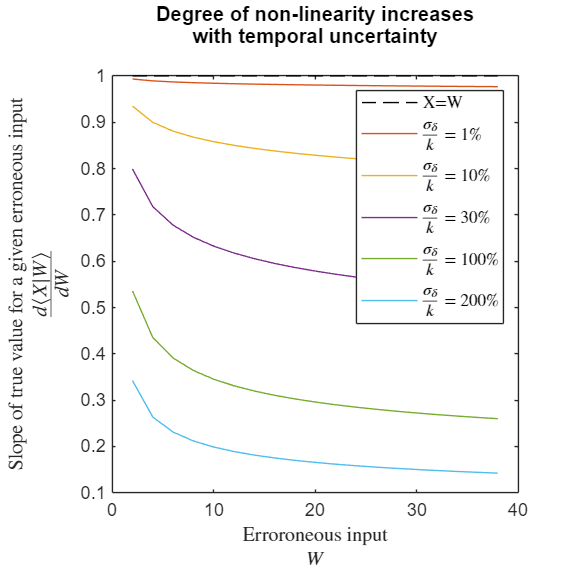

figA1=figure;
resize_figure(figA1,2*55,2*55);
mwbin = 0.5.*(wbin(1:end-1)+wbin(2:end));
plot(mwbin,diff(wbin)./diff(wbin),'--k');
hold on;
plot(mwbin,diff(xT1)./diff(wbin));
hold on;
plot(mwbin,diff(xT2)./diff(wbin));
hold on;
plot(mwbin,diff(xT3)./diff(wbin));
hold on;
plot(mwbin,diff(xT4)./diff(wbin));
hold on;
plot(mwbin,diff(xT5)./diff(wbin));
title({'Degree of non-linearity increases','with temporal uncertainty'},' ','Interpreter','none')
xlabel({'Erroroneous input','$W$'},'Interpreter','Latex');
ylabel({'Slope of true value for a given erroneous input','$\frac{d\langle X|W \rangle}{dW} $'},'Interpreter','Latex');
legend(['X=W'],...
    ['$\frac{\sigma_{\delta}}{k}$ = $1\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $10\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $30\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $100\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $200\%$'], ...
    'Interpreter','latex','Location','northeast');

% export_fig([outputFolder,'FigureM4_1.png'], ...
%     '-r600','-png','-nocrop',figA1);
% export_fig([outputFolder,'FigureM4_1.pdf'], ...
%     '-r600','-pdf','-nocrop',figA1);

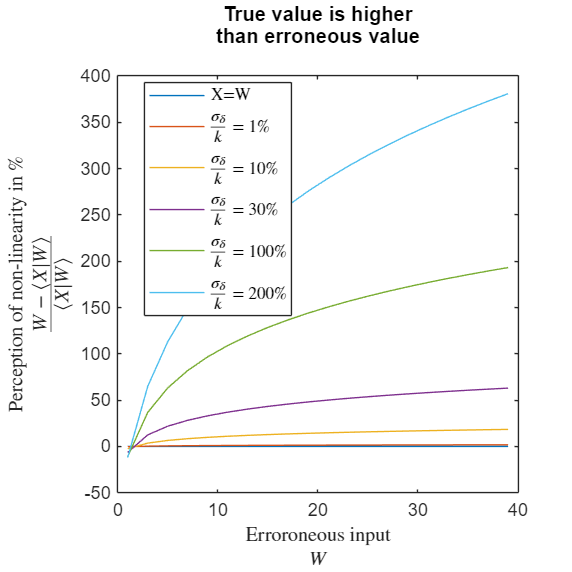

figA2=figure;
resize_figure(figA2,2*55,2*55);
plot(wbin,100.*(wbin./wbin-1));
hold on;
plot(wbin,100.*(wbin./xT1-1));
hold on;
plot(wbin,100.*(wbin./xT2-1));
hold on;
plot(wbin,100.*(wbin./xT3-1));
hold on;
plot(wbin,100.*(wbin./xT4-1));
hold on;
plot(wbin,100.*(wbin./xT5-1));
title({'True value is higher','than erroneous value'},' ','Interpreter','none')
xlabel({'Erroroneous input','$W$'},'Interpreter','Latex');
ylabel({'Perception of non-linearity in $\%$','$\frac{W-\langle X|W \rangle}{\langle X|W \rangle} $'},'Interpreter','Latex');
legend(['X=W'],...
    ['$\frac{\sigma_{\delta}}{k}$ = $1\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $10\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $30\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $100\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $200\%$'], ...
    'Interpreter','latex','Location','best');

% export_fig([outputFolder,'FigureM4_2.png'], ...
%     '-r600','-png','-nocrop',figA2);
% export_fig([outputFolder,'FigureM4_2.pdf'], ...
%     '-r600','-pdf','-nocrop',figA2);


## Monte-Carlo validation

Validating the results of the analytical derivation with that of a Monte-Carlo simulation. 

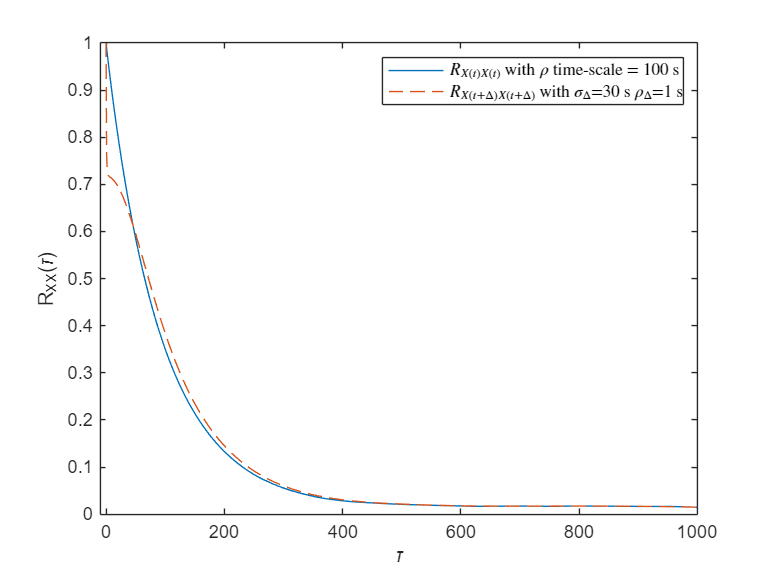

dt = 1;
nSamples = 2^12;
nEnsembles = 10000;
lag = fftshift(-nSamples:1:nSamples-1)'.*dt;

tau = 100; % Autocorrelation time constant k
Rm = acf(abs(lag),tau);
RmMatrix = toeplitz(Rm(find(lag==0):find(lag==(nSamples-1)*dt)));
X = MvLogNRand(repmat(-0.2518,nSamples,1),repmat(0.85,nSamples,1),nEnsembles,RmMatrix);

deltaT = 30; % Standard deviation of time uncertainty: sigma_D 
tau_D = 1; % The autocorrelation time constant of the time uncertainty
Rmd = acf(abs(lag),tau_D);
RmdMatrix = toeplitz(Rmd(find(lag==0):find(lag==(nSamples-1)*dt)));
D = mvnrnd(zeros(1,nSamples),corr2cov(repmat(deltaT,nSamples,1), RmdMatrix),nEnsembles);

time = ((1:1:nSamples).*dt-1);
scatteredTime = time + D; 
scatteredTime(scatteredTime<0) = nSamples + scatteredTime(scatteredTime<0);
scatteredTime(scatteredTime>nSamples-1) = scatteredTime(scatteredTime>nSamples-1) - (nSamples-1);
W = zeros(nEnsembles,nSamples);
time1 = zeros(1,nSamples+2);
time1(1) = -1;
time1(2:end-1) = time;
time1(end) = time(end)+1;
X1 = zeros(nEnsembles,nSamples+2);
X1(:,1) = X(:,end);
X1(:,2:end-1) = X(:,1:end);
X1(:,end) = X(:,1);
for i=1:1:nEnsembles
    W(i,:) = interp1(time1,X1(i,:),scatteredTime(i,:));
end

M = W;
[RArrayXN,lagXN] = find_correlation(M-nanmean(M,1),nSamples,nEnsembles,1);

acf_W = mean(RArrayXN(:,1:2^12)./RArrayXN(:,1));
lag_W = lagXN(1:2^12);
acf_fit_W = fit(lag_W,acf_W','spline'); % Fitting the ACF with a spline!

M = X;
[RArrayXN1,lagXN] = find_correlation(M-nanmean(M,1),nSamples,nEnsembles,1);

acf_X = mean(RArrayXN1(:,1:2^12)./RArrayXN1(:,1));
lag_X = lagXN(1:2^12);
acf_fit_X = fit(lag_X,acf_X','spline'); % Fitting the ACF with a spline!

figure; 
tInd = 0:1000;
% plot(tInd,acf(tInd,tau));
% hold on;
plot(tInd,acf_fit_X(tInd));
hold on;
plot(tInd,acf_fit_W(tInd),'--');
xlabel('\tau');
ylabel('R_{XX}(\tau)');
legend(['$R_{X(t)X(t)}$ with $\rho$ time-scale = ',num2str(tau),' s'], ...
    ['$R_{X(t+\Delta)X(t+\Delta)}$ with $\sigma_{\Delta}$=',num2str(deltaT),' s', ...
    ' $\rho_{\Delta}$=',num2str(tau_D),' s'],'Interpreter','latex');
xlim([-10,1000]);

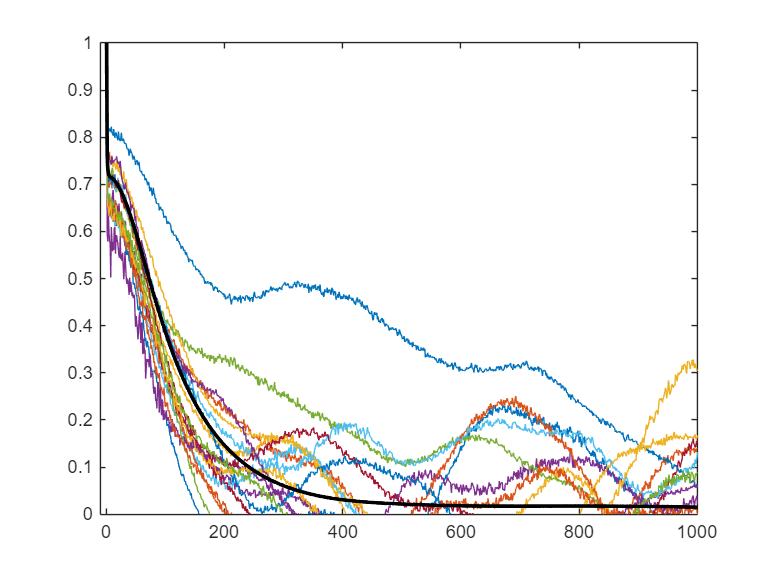

figure;
plot(RArrayXN(2:20,1:2^12)'./RArrayXN(2:20,1)');
hold on;
plot(mean(RArrayXN(:,1:2^12)./RArrayXN(:,1)),'k','LineWidth',2);
ylim([0,1]);
xlim([-10,1000]);

XBins = 0:1:40;
EXgW = create_curve(W(:),X(:),XBins);

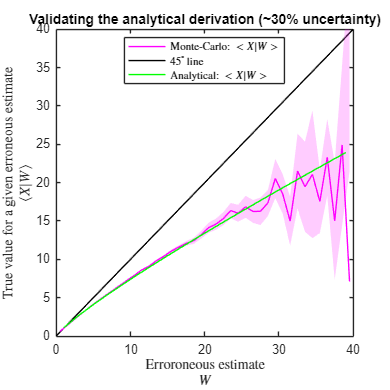

figM2=figure;
resize_figure(figM2,2*55,2*55);
p0 = plot(XBins,XBins,'-k');
hold on;
p1 = plot_curve(EXgW,'m'); % model
hold on;
p2=plot(wbin,xT3,'g');

ylim([0,40]);
xlim([0,40]);
xlabel({'Erroroneous estimate','$W$'},'Interpreter','Latex');
ylabel({'True value for a given erroneous estimate','$\langle X|W \rangle$'},'Interpreter','Latex');
legend([p1,p0,p2],...
    'Monte-Carlo: $<X|W>$',...
    '45$^\circ$ line', ...
    'Analytical: $<X|W>$',...
    'Interpreter',"latex",'Location','best');
title('Validating the analytical derivation (~30% uncertainty)','Interpreter',"none");

The above plot shows that the analytical derivation results in the same non-linearly biased regression function as that generated from the monte-carlo simulation. 

function RmArray=acf(lag,tau)

    RmArray = exp(-abs(lag).*tau.^-1);

end

function [edges, value] = create_segmented_pdfs(X,Y,XBins,XSegments,normalizationStr)

**create_segmented_pdfs(): **Creating histograms of probability distributions, which can be colored to show a form of conditional probability distribution. (See figure).

if nargin<5
    normalizationStr = 'countdensity';
end

value = zeros(length(XSegments),length(XBins)-1);
for i=1:1:length(XSegments)
    if i==1
        [value(i,:),edges] = histcounts(Y(X<=XSegments(i)),XBins,'Normalization',normalizationStr);
        edges = edges(2:end) - (edges(2)-edges(1))/2;
    elseif i>1 && i < length(XSegments)
        value(i,:) = histcounts(Y(X>XSegments(i-1) & X<=XSegments(i)),XBins,'Normalization',normalizationStr);
    else
       value(i,:) = histcounts(Y(X>=XSegments(i-1)),XBins,'Normalization',normalizationStr);
    end
    
end

end


function p = plot_curve(curve, color)

CI1 = interp_nans(curve.CI);
p=plot(curve.XBins, curve.YgX, 'Color', color);
hold on;
plot_ci(curve.XBins,CI1,color,0.2);
end

function plot_ci(x,ci,color,alpha)
    hold on;
    X2 = [x, fliplr(x)];
    inBetween = [ci(:,1)', fliplr(ci(:,2)')];
    fill(X2,inBetween,color,'LineStyle','none','FaceAlpha',alpha);
end

function p = plot_2D_error(Y,X,P,yLabel)
    p = pcolor(Y,X,P);
    set(p,'EdgeColor','none');
    colorbar_thin('YLabel',yLabel);
end

function curve = create_curve(X, Y, Ei)

if nargin<3
    Ei = 100;
end
Y = Y(:);
Y(Y==999999)=nan;

X1 = X(~isnan(X) & ~isnan(Y));
Y1 = Y(~isnan(X) & ~isnan(Y));
X = X1;
Y = Y1;

[xindx, E] = discretize(X(:),Ei);

for i = 1:max(xindx)
    curve.YgX(i) = nanmean(Y(xindx==i));
    curve.stdYgX(i) = nanstd(Y(xindx==i));
    curve.NSamples(i) = sum(xindx==i & ~isnan(Y));
    curve.SEM(i) = nanstd(Y(xindx==i))./sqrt(curve.NSamples(i));
    curve.ts(i,:) = tinv([0.025 0.975],curve.NSamples(i)-1);
    curve.CI(i,:) = curve.YgX(i) + curve.ts(i,:)*curve.SEM(i);
    curve.XBins(i) = 0.5*(E(i)+E(i+1));
end

curve.E = E; 

end

function [fXgY,XX,YY] = conditional_pdf(X, Y, gridx, gridy)

X1 = X(~isnan(X) & ~isnan(Y));
Y1 = Y(~isnan(X) & ~isnan(Y));
X = X1;
Y = Y1;

sz = 2^10;
Y = Y(:);
Y(Y==999999)=nan;

[bandwidth,fXY,XX,YY]=kde2d([X,Y],sz,[min(gridx),min(gridy)],[max(gridx),max(gridy)]);
[fY, YY1] = ksdensity(Y,YY(:,1));

fXgY = fXY./repmat(fY,1,sz);


The above formula is basically equation 1, below. 

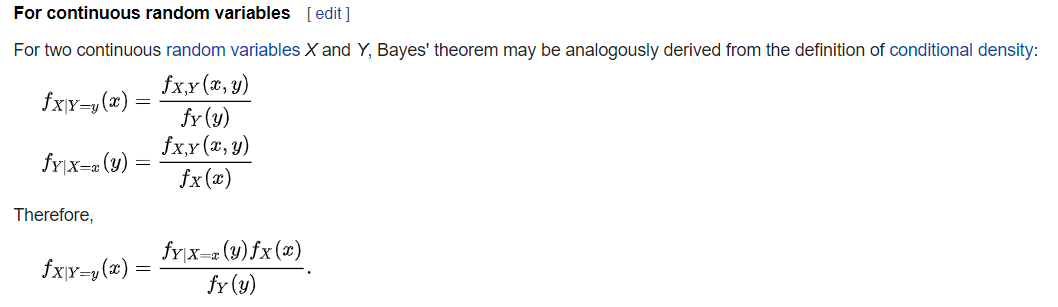


end


function [M, nSample, nEnsemble]= split_series(series,sampleSize,MaxNoOfMissingValues)
    if nargin<3
        MaxNoOfMissingValues=1000;
    end
        
    series = padarray(series,sampleSize-mod(length(series),sampleSize),'post');
    L = length(series); 
    M0 = reshape(series,sampleSize,[])';
    indx=sum(isnan(M0),2)>MaxNoOfMissingValues;
    l = 1:1:size(M0,1);
    k=1;
    for i=l(~indx)
        M(k,:) = M0(i,:);
        k=k+1;
    end
    nSample = size(M,2);
    nEnsemble = size(M,1);
    
    M = interp_nans(M')';
end

function [RArray,lag]=find_correlation(M,nSample,nEnsemble,sampleTime)
    dt = sampleTime;
    lag = fftshift(-nSample:1:nSample-1)'.*dt;
    xCell = mat2cell(M, ones(1,nEnsemble),nSample);
    [RArray] = cellfun(@(x) xcorr(x,'unbiased'),xCell,'UniformOutput',false);
    RArray = cell2mat(RArray);
    RArray(:,2:end+1) = RArray(:,1:end);
    RArray(:,1)=RArray(:,2);
    RArray = ifftshift(RArray);
end



## External Functions

Acknowledging the use of two external functions: 

1) Stephen Lienhard (2021). Multivariate Lognormal Simulation with Correlation (https://www.mathworks.com/matlabcentral/fileexchange/6426-multivariate-lognormal-simulation-with-correlation), MATLAB Central File Exchange. Retrieved October 7, 2021.

2) Zdravko Botev (2021). kernel density estimation (https://www.mathworks.com/matlabcentral/fileexchange/17204-kernel-density-estimation), MATLAB Central File Exchange. Retrieved October 7, 2021.

### Stochastic process from Log-normal distribution

MVLOGNRAND MultiVariant Lognormal random numbers with correlation

function y = MvLogNRand( Mu , Sigma , Simulations , CorrMat )
%MVLOGNRAND MultiVariant Lognormal random numbers with correlation
%
%   Mu: The Lognormal parameter Mu  (can be column or row vector)
%
%   Sigma: The Lognormal parameter Sigma (can be column or row vector)
%
%   Simulations:  The Number of simulations to run (scalar)
%
%   CorrMat:  OPTIONAL A square matrix with the number of rows and columns
%   equal to the number of elements in Mu/Sigma.  Each element on the
%   diagonal is equal to one, with the off diagonal cells equal to the
%   correlation of the marginal Lognormal distributions. If not specified,
%   then assume zero correlation.
%
%   To check the simulation run corrcoef(Y) and that should be the same as
%   your CorrMat.
%
%   REQUIRES THE STATISTICS TOOLBOX
%
%   Example:
%   Mu    = [ 11 12 13 ];
%   Sigma = [ .1 .3 .5 ];
%   Simulations = 1e6;
%   CorrMat = [1 .2 .4 ; .2 1 .5 ; .4  .5 1];
%   y = MvLogNRand( Mu , Sigma , Simulations , CorrMat );
%
%   corrcoef(y)
%   ans =
%            1      0.19927      0.40156
%      0.19927            1      0.50008
%      0.40156      0.50008            1
%
%   CorrMat =
%               1          0.2          0.4
%             0.2            1          0.5
%             0.4          0.5            1
%
%   For more information see: Aggregration of Correlated Risk Portfolios:
%   Models and Algorithms; Shaun S. Wang, Phd.  Casualty Actuarial Society
%   Proceedings Volume LXXXV www.casact.org
%
%   Author: Stephen Lienhard
% Error checking
if nargin < 3
    error('Must have at least 3 input arguements')
end
if numel(Simulations) ~= 1 || Simulations < 0
    error('The number of simulations must be greater then zero and a scalar')
end
if nargin == 3
    CorrMat = eye(numel(Mu));
elseif size(CorrMat,1) ~= size(CorrMat,2)
    error('The correlation matrix must have the same number of rows as columns')
end
if numel(Mu) ~= numel(Sigma)
    error('Mu and Sigma must have the same number of elements')
end
% Force column vectors
Mu     = Mu(:);
Sigma  = Sigma(:);
% Calculate the covariance structure
sigma_down = repmat( Sigma' , numel(Sigma), 1            );
sigma_acrs = repmat( Sigma  , 1           , numel(Sigma) );
covv = log( CorrMat .* sqrt(exp(sigma_down.^2)-1) .* ...
                       sqrt(exp(sigma_acrs.^2)-1) + 1 );
% The Simulation
y = exp( mvnrnd( Mu , covv , Simulations ));
end

function y = MvNRand( Mu , Sigma , Simulations , CorrMat )
%MVLOGNRAND MultiVariant Lognormal random numbers with correlation
%
%   Mu: The Lognormal parameter Mu  (can be column or row vector)
%
%   Sigma: The Lognormal parameter Sigma (can be column or row vector)
%
%   Simulations:  The Number of simulations to run (scalar)
%
%   CorrMat:  OPTIONAL A square matrix with the number of rows and columns
%   equal to the number of elements in Mu/Sigma.  Each element on the
%   diagonal is equal to one, with the off diagonal cells equal to the
%   correlation of the marginal Lognormal distributions. If not specified,
%   then assume zero correlation.
%
%   To check the simulation run corrcoef(Y) and that should be the same as
%   your CorrMat.
%
%   REQUIRES THE STATISTICS TOOLBOX
%
%   Example:
%   Mu    = [ 11 12 13 ];
%   Sigma = [ .1 .3 .5 ];
%   Simulations = 1e6;
%   CorrMat = [1 .2 .4 ; .2 1 .5 ; .4  .5 1];
%   y = MvLogNRand( Mu , Sigma , Simulations , CorrMat );
%
%   corrcoef(y)
%   ans =
%            1      0.19927      0.40156
%      0.19927            1      0.50008
%      0.40156      0.50008            1
%
%   CorrMat =
%               1          0.2          0.4
%             0.2            1          0.5
%             0.4          0.5            1
%
%   For more information see: Aggregration of Correlated Risk Portfolios:
%   Models and Algorithms; Shaun S. Wang, Phd.  Casualty Actuarial Society
%   Proceedings Volume LXXXV www.casact.org
%
%   Author: Stephen Lienhard
% Error checking
if nargin < 3
    error('Must have at least 3 input arguements')
end
if numel(Simulations) ~= 1 || Simulations < 0
    error('The number of simulations must be greater then zero and a scalar')
end
if nargin == 3
    CorrMat = eye(numel(Mu));
elseif size(CorrMat,1) ~= size(CorrMat,2)
    error('The correlation matrix must have the same number of rows as columns')
end
if numel(Mu) ~= numel(Sigma)
    error('Mu and Sigma must have the same number of elements')
end
% Force column vectors
Mu     = Mu(:);
Sigma  = Sigma(:);
% Calculate the covariance structure
sigma_down = repmat( Sigma' , numel(Sigma), 1            );
sigma_acrs = repmat( Sigma  , 1           , numel(Sigma) );
covv = log( CorrMat .* sqrt(exp(sigma_down.^2)-1) .* ...
                       sqrt(exp(sigma_acrs.^2)-1) + 1 );
% The Simulation
y = mvnrnd( Mu , covv , Simulations );
end

function y = MvtRand( Mu , Nu , Simulations , CorrMat )
%MVLOGNRAND MultiVariant Lognormal random numbers with correlation
%
%   Mu: The Lognormal parameter Mu  (can be column or row vector)
%
%   Sigma: The Lognormal parameter Sigma (can be column or row vector)
%
%   Simulations:  The Number of simulations to run (scalar)
%
%   CorrMat:  OPTIONAL A square matrix with the number of rows and columns
%   equal to the number of elements in Mu/Sigma.  Each element on the
%   diagonal is equal to one, with the off diagonal cells equal to the
%   correlation of the marginal Lognormal distributions. If not specified,
%   then assume zero correlation.
%
%   To check the simulation run corrcoef(Y) and that should be the same as
%   your CorrMat.
%
%   REQUIRES THE STATISTICS TOOLBOX
%
%   Example:
%   Mu    = [ 11 12 13 ];
%   Sigma = [ .1 .3 .5 ];
%   Simulations = 1e6;
%   CorrMat = [1 .2 .4 ; .2 1 .5 ; .4  .5 1];
%   y = MvLogNRand( Mu , Sigma , Simulations , CorrMat );
%
%   corrcoef(y)
%   ans =
%            1      0.19927      0.40156
%      0.19927            1      0.50008
%      0.40156      0.50008            1
%
%   CorrMat =
%               1          0.2          0.4
%             0.2            1          0.5
%             0.4          0.5            1
%
%   For more information see: Aggregration of Correlated Risk Portfolios:
%   Models and Algorithms; Shaun S. Wang, Phd.  Casualty Actuarial Society
%   Proceedings Volume LXXXV www.casact.org
%
%   Author: Stephen Lienhard
% Error checking
if nargin < 3
    error('Must have at least 3 input arguements')
end
if numel(Simulations) ~= 1 || Simulations < 0
    error('The number of simulations must be greater then zero and a scalar')
end
if nargin == 3
    CorrMat = eye(numel(Mu));
elseif size(CorrMat,1) ~= size(CorrMat,2)
    error('The correlation matrix must have the same number of rows as columns')
end

% Force column vectors
Mu     = Mu(:);
% Calculate the covariance structure
% sigma_down = repmat( Sigma' , numel(Sigma), 1            );
% sigma_acrs = repmat( Sigma  , 1           , numel(Sigma) );
% covv = log( CorrMat .* sqrt(exp(sigma_down.^2)-1) .* ...
%                        sqrt(exp(sigma_acrs.^2)-1) + 1 );
% The Simulation
y = Mu' + mvtrnd(CorrMat, Nu, Simulations);
end

### KDE2D

fast and accurate state-of-the-art bivariate kernel density estimator with diagonal bandwidth matrix.

function [bandwidth,density,X,Y]=kde2d(data,n,MIN_XY,MAX_XY)
% fast and accurate state-of-the-art
% bivariate kernel density estimator
% with diagonal bandwidth matrix.
% The kernel is assumed to be Gaussian.
% The two bandwidth parameters are
% chosen optimally without ever
% using/assuming a parametric model for the data or any "rules of thumb".
% Unlike many other procedures, this one
% is immune to accuracy failures in the estimation of
% multimodal densities with widely separated modes (see examples).
% INPUTS: data - an N by 2 array with continuous data
%            n - size of the n by n grid over which the density is computed
%                n has to be a power of 2, otherwise n=2^ceil(log2(n));
%                the default value is 2^8;
% MIN_XY,MAX_XY- limits of the bounding box over which the density is computed;
%                the format is:
%                MIN_XY=[lower_Xlim,lower_Ylim]
%                MAX_XY=[upper_Xlim,upper_Ylim].
%                The dafault limits are computed as:
%                MAX=max(data,[],1); MIN=min(data,[],1); Range=MAX-MIN;
%                MAX_XY=MAX+Range/4; MIN_XY=MIN-Range/4;
% OUTPUT: bandwidth - a row vector with the two optimal
%                     bandwidths for a bivaroate Gaussian kernel;
%                     the format is:
%                     bandwidth=[bandwidth_X, bandwidth_Y];
%          density  - an n by n matrix containing the density values over the n by n grid;
%                     density is not computed unless the function is asked for such an output;
%              X,Y  - the meshgrid over which the variable "density" has been computed;
%                     the intended usage is as follows:
%                     surf(X,Y,density)
% Example (simple Gaussian mixture)
% clear all
%   % generate a Gaussian mixture with distant modes
%   data=[randn(500,2);
%       randn(500,1)+3.5, randn(500,1);];
%   % call the routine
%     [bandwidth,density,X,Y]=kde2d(data);
%   % plot the data and the density estimate
%     contour3(X,Y,density,50), hold on
%     plot(data(:,1),data(:,2),'r.','MarkerSize',5)
%
% Example (Gaussian mixture with distant modes):
%
% clear all
%  % generate a Gaussian mixture with distant modes
%  data=[randn(100,1), randn(100,1)/4;
%      randn(100,1)+18, randn(100,1);
%      randn(100,1)+15, randn(100,1)/2-18;];
%  % call the routine
%    [bandwidth,density,X,Y]=kde2d(data);
%  % plot the data and the density estimate
%  surf(X,Y,density,'LineStyle','none'), view([0,60])
%  colormap hot, hold on, alpha(.8)
%  set(gca, 'color', 'blue');
%  plot(data(:,1),data(:,2),'w.','MarkerSize',5)
%
% Example (Sinusoidal density):
%
% clear all
%   X=rand(1000,1); Y=sin(X*10*pi)+randn(size(X))/3; data=[X,Y];
%  % apply routine
%  [bandwidth,density,X,Y]=kde2d(data);
%  % plot the data and the density estimate
%  surf(X,Y,density,'LineStyle','none'), view([0,70])
%  colormap hot, hold on, alpha(.8)
%  set(gca, 'color', 'blue');
%  plot(data(:,1),data(:,2),'w.','MarkerSize',5)
%
%  Reference:
% Kernel density estimation via diffusion
% Z. I. Botev, J. F. Grotowski, and D. P. Kroese (2010)
% Annals of Statistics, Volume 38, Number 5, pages 2916-2957.
global N A2 I
if nargin<2
    n=2^8;
end
n=2^ceil(log2(n)); % round up n to the next power of 2;
N=size(data,1);
if nargin<3
    MAX=max(data,[],1); MIN=min(data,[],1); Range=MAX-MIN;
    MAX_XY=MAX+Range/2; MIN_XY=MIN-Range/2;
end
scaling=MAX_XY-MIN_XY;
if N<=size(data,2)
    error('data has to be an N by 2 array where each row represents a two dimensional observation')
end
transformed_data=(data-repmat(MIN_XY,N,1))./repmat(scaling,N,1);
%bin the data uniformly using regular grid;
initial_data=ndhist(transformed_data,n);
% discrete cosine transform of initial data
a= dct2d(initial_data);
% now compute the optimal bandwidth^2
  I=(0:n-1).^2; A2=a.^2;
 t_star=root(@(t)(t-evolve(t)),N);
p_02=func([0,2],t_star);p_20=func([2,0],t_star); p_11=func([1,1],t_star);
t_y=(p_02^(3/4)/(4*pi*N*p_20^(3/4)*(p_11+sqrt(p_20*p_02))))^(1/3);
t_x=(p_20^(3/4)/(4*pi*N*p_02^(3/4)*(p_11+sqrt(p_20*p_02))))^(1/3);
% smooth the discrete cosine transform of initial data using t_star
a_t=exp(-(0:n-1)'.^2*pi^2*t_x/2)*exp(-(0:n-1).^2*pi^2*t_y/2).*a; 
% now apply the inverse discrete cosine transform
if nargout>1
    density=idct2d(a_t)*(numel(a_t)/prod(scaling));
	density(density<0)=eps; % remove any negative density values
    [X,Y]=meshgrid(MIN_XY(1):scaling(1)/(n-1):MAX_XY(1),MIN_XY(2):scaling(2)/(n-1):MAX_XY(2));
end
bandwidth=sqrt([t_x,t_y]).*scaling; 
end
%#######################################
function  [out,time]=evolve(t)
global N
Sum_func = func([0,2],t) + func([2,0],t) + 2*func([1,1],t);
time=(2*pi*N*Sum_func)^(-1/3);
out=(t-time)/time;
end
%#######################################
function out=func(s,t)
global N
if sum(s)<=4
    Sum_func=func([s(1)+1,s(2)],t)+func([s(1),s(2)+1],t); const=(1+1/2^(sum(s)+1))/3;
    time=(-2*const*K(s(1))*K(s(2))/N/Sum_func)^(1/(2+sum(s)));
    out=psi(s,time);
else
    out=psi(s,t);
end
end
%#######################################
function out=psi(s,Time)
global I A2
% s is a vector
w=exp(-I*pi^2*Time).*[1,.5*ones(1,length(I)-1)];
wx=w.*(I.^s(1));
wy=w.*(I.^s(2));
out=(-1)^sum(s)*(wy*A2*wx')*pi^(2*sum(s));
end
%#######################################
function out=K(s)
out=(-1)^s*prod((1:2:2*s-1))/sqrt(2*pi);
end
%#######################################
function data=dct2d(data)
% computes the 2 dimensional discrete cosine transform of data
% data is an nd cube
[nrows,ncols]= size(data);
if nrows~=ncols
    error('data is not a square array!')
end
% Compute weights to multiply DFT coefficients
w = [1;2*(exp(-i*(1:nrows-1)*pi/(2*nrows))).'];
weight=w(:,ones(1,ncols));
data=dct1d(dct1d(data)')';
    function transform1d=dct1d(x)
        % Re-order the elements of the columns of x
        x = [ x(1:2:end,:); x(end:-2:2,:) ];
        % Multiply FFT by weights:
        transform1d = real(weight.* fft(x));
    end
end
%#######################################
function data = idct2d(data)
% computes the 2 dimensional inverse discrete cosine transform
[nrows,ncols]=size(data);
% Compute wieghts
w = exp(i*(0:nrows-1)*pi/(2*nrows)).';
weights=w(:,ones(1,ncols));
data=idct1d(idct1d(data)');
    function out=idct1d(x)
        y = real(ifft(weights.*x));
        out = zeros(nrows,ncols);
        out(1:2:nrows,:) = y(1:nrows/2,:);
        out(2:2:nrows,:) = y(nrows:-1:nrows/2+1,:);
    end
end
%#######################################
function binned_data=ndhist(data,M)
% this function computes the histogram
% of an n-dimensional data set;
% 'data' is nrows by n columns
% M is the number of bins used in each dimension
% so that 'binned_data' is a hypercube with
% size length equal to M;
[nrows,ncols]=size(data);
bins=zeros(nrows,ncols);
for i=1:ncols
    [dum,bins(:,i)] = histc(data(:,i),[0:1/M:1],1);
    bins(:,i) = min(bins(:,i),M);
end
% Combine the  vectors of 1D bin counts into a grid of nD bin
% counts.
binned_data = accumarray(bins(all(bins>0,2),:),1/nrows,M(ones(1,ncols)));
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function t=root(f,N)
% try to find smallest root whenever there is more than one
N=50*(N<=50)+1050*(N>=1050)+N*((N<1050)&(N>50));
tol=10^-12+0.01*(N-50)/1000;
flag=0;
while flag==0
    try
        t=fzero(f,[0,tol]);
        flag=1;
    catch
        tol=min(tol*2,.1); % double search interval
    end
    if tol==.1 % if all else fails
        t=fminbnd(@(x)abs(f(x)),0,.1); flag=1;
    end
end
end


function resize_figure( figureHandle, vert, horz )
%% resize_figure.m Resizes figure into a standard paper size
%--------------------------------------------------------------------------
% Input
%------
% figureHandle
% vert - Vertical page size in mm (Default Letter Size)
% horz - Horizontal page size in mm (Default Letter Size)

if nargin<3 || isempty(horz)
    horz = 215.9;
end
if nargin<2 || isempty(vert)
    vert = 279.4;
end

% Centimeter Units
X = horz/10;
Y = vert/10;
xMargin = 0;
yMargin = 0;
xSize = X - 2*xMargin;
ySize = Y - 2*yMargin;

% Figure size displayed on screen
movegui(figureHandle, 'center');
set(figureHandle,'color','w');�
set(figureHandle, 'Units', 'centimeters', 'Position', [0 0 xSize ySize])
end

function [cm_data]=inferno(m)

cm = [[  1.46159096e-03,   4.66127766e-04,   1.38655200e-02],
       [  2.26726368e-03,   1.26992553e-03,   1.85703520e-02],
       [  3.29899092e-03,   2.24934863e-03,   2.42390508e-02],
       [  4.54690615e-03,   3.39180156e-03,   3.09092475e-02],
       [  6.00552565e-03,   4.69194561e-03,   3.85578980e-02],
       [  7.67578856e-03,   6.13611626e-03,   4.68360336e-02],
       [  9.56051094e-03,   7.71344131e-03,   5.51430756e-02],
       [  1.16634769e-02,   9.41675403e-03,   6.34598080e-02],
       [  1.39950388e-02,   1.12247138e-02,   7.18616890e-02],
       [  1.65605595e-02,   1.31362262e-02,   8.02817951e-02],
       [  1.93732295e-02,   1.51325789e-02,   8.87668094e-02],
       [  2.24468865e-02,   1.71991484e-02,   9.73274383e-02],
       [  2.57927373e-02,   1.93306298e-02,   1.05929835e-01],
       [  2.94324251e-02,   2.15030771e-02,   1.14621328e-01],
       [  3.33852235e-02,   2.37024271e-02,   1.23397286e-01],
       [  3.76684211e-02,   2.59207864e-02,   1.32232108e-01],
       [  4.22525554e-02,   2.81385015e-02,   1.41140519e-01],
       [  4.69146287e-02,   3.03236129e-02,   1.50163867e-01],
       [  5.16437624e-02,   3.24736172e-02,   1.59254277e-01],
       [  5.64491009e-02,   3.45691867e-02,   1.68413539e-01],
       [  6.13397200e-02,   3.65900213e-02,   1.77642172e-01],
       [  6.63312620e-02,   3.85036268e-02,   1.86961588e-01],
       [  7.14289181e-02,   4.02939095e-02,   1.96353558e-01],
       [  7.66367560e-02,   4.19053329e-02,   2.05798788e-01],
       [  8.19620773e-02,   4.33278666e-02,   2.15289113e-01],
       [  8.74113897e-02,   4.45561662e-02,   2.24813479e-01],
       [  9.29901526e-02,   4.55829503e-02,   2.34357604e-01],
       [  9.87024972e-02,   4.64018731e-02,   2.43903700e-01],
       [  1.04550936e-01,   4.70080541e-02,   2.53430300e-01],
       [  1.10536084e-01,   4.73986708e-02,   2.62912235e-01],
       [  1.16656423e-01,   4.75735920e-02,   2.72320803e-01],
       [  1.22908126e-01,   4.75360183e-02,   2.81624170e-01],
       [  1.29284984e-01,   4.72930838e-02,   2.90788012e-01],
       [  1.35778450e-01,   4.68563678e-02,   2.99776404e-01],
       [  1.42377819e-01,   4.62422566e-02,   3.08552910e-01],
       [  1.49072957e-01,   4.54676444e-02,   3.17085139e-01],
       [  1.55849711e-01,   4.45588056e-02,   3.25338414e-01],
       [  1.62688939e-01,   4.35542881e-02,   3.33276678e-01],
       [  1.69575148e-01,   4.24893149e-02,   3.40874188e-01],
       [  1.76493202e-01,   4.14017089e-02,   3.48110606e-01],
       [  1.83428775e-01,   4.03288858e-02,   3.54971391e-01],
       [  1.90367453e-01,   3.93088888e-02,   3.61446945e-01],
       [  1.97297425e-01,   3.84001825e-02,   3.67534629e-01],
       [  2.04209298e-01,   3.76322609e-02,   3.73237557e-01],
       [  2.11095463e-01,   3.70296488e-02,   3.78563264e-01],
       [  2.17948648e-01,   3.66146049e-02,   3.83522415e-01],
       [  2.24762908e-01,   3.64049901e-02,   3.88128944e-01],
       [  2.31538148e-01,   3.64052511e-02,   3.92400150e-01],
       [  2.38272961e-01,   3.66209949e-02,   3.96353388e-01],
       [  2.44966911e-01,   3.70545017e-02,   4.00006615e-01],
       [  2.51620354e-01,   3.77052832e-02,   4.03377897e-01],
       [  2.58234265e-01,   3.85706153e-02,   4.06485031e-01],
       [  2.64809649e-01,   3.96468666e-02,   4.09345373e-01],
       [  2.71346664e-01,   4.09215821e-02,   4.11976086e-01],
       [  2.77849829e-01,   4.23528741e-02,   4.14392106e-01],
       [  2.84321318e-01,   4.39325787e-02,   4.16607861e-01],
       [  2.90763373e-01,   4.56437598e-02,   4.18636756e-01],
       [  2.97178251e-01,   4.74700293e-02,   4.20491164e-01],
       [  3.03568182e-01,   4.93958927e-02,   4.22182449e-01],
       [  3.09935342e-01,   5.14069729e-02,   4.23720999e-01],
       [  3.16281835e-01,   5.34901321e-02,   4.25116277e-01],
       [  3.22609671e-01,   5.56335178e-02,   4.26376869e-01],
       [  3.28920763e-01,   5.78265505e-02,   4.27510546e-01],
       [  3.35216916e-01,   6.00598734e-02,   4.28524320e-01],
       [  3.41499828e-01,   6.23252772e-02,   4.29424503e-01],
       [  3.47771086e-01,   6.46156100e-02,   4.30216765e-01],
       [  3.54032169e-01,   6.69246832e-02,   4.30906186e-01],
       [  3.60284449e-01,   6.92471753e-02,   4.31497309e-01],
       [  3.66529195e-01,   7.15785403e-02,   4.31994185e-01],
       [  3.72767575e-01,   7.39149211e-02,   4.32400419e-01],
       [  3.79000659e-01,   7.62530701e-02,   4.32719214e-01],
       [  3.85228383e-01,   7.85914864e-02,   4.32954973e-01],
       [  3.91452659e-01,   8.09267058e-02,   4.33108763e-01],
       [  3.97674379e-01,   8.32568129e-02,   4.33182647e-01],
       [  4.03894278e-01,   8.55803445e-02,   4.33178526e-01],
       [  4.10113015e-01,   8.78961593e-02,   4.33098056e-01],
       [  4.16331169e-01,   9.02033992e-02,   4.32942678e-01],
       [  4.22549249e-01,   9.25014543e-02,   4.32713635e-01],
       [  4.28767696e-01,   9.47899342e-02,   4.32411996e-01],
       [  4.34986885e-01,   9.70686417e-02,   4.32038673e-01],
       [  4.41207124e-01,   9.93375510e-02,   4.31594438e-01],
       [  4.47428382e-01,   1.01597079e-01,   4.31080497e-01],
       [  4.53650614e-01,   1.03847716e-01,   4.30497898e-01],
       [  4.59874623e-01,   1.06089165e-01,   4.29845789e-01],
       [  4.66100494e-01,   1.08321923e-01,   4.29124507e-01],
       [  4.72328255e-01,   1.10546584e-01,   4.28334320e-01],
       [  4.78557889e-01,   1.12763831e-01,   4.27475431e-01],
       [  4.84789325e-01,   1.14974430e-01,   4.26547991e-01],
       [  4.91022448e-01,   1.17179219e-01,   4.25552106e-01],
       [  4.97257069e-01,   1.19379132e-01,   4.24487908e-01],
       [  5.03492698e-01,   1.21575414e-01,   4.23356110e-01],
       [  5.09729541e-01,   1.23768654e-01,   4.22155676e-01],
       [  5.15967304e-01,   1.25959947e-01,   4.20886594e-01],
       [  5.22205646e-01,   1.28150439e-01,   4.19548848e-01],
       [  5.28444192e-01,   1.30341324e-01,   4.18142411e-01],
       [  5.34682523e-01,   1.32533845e-01,   4.16667258e-01],
       [  5.40920186e-01,   1.34729286e-01,   4.15123366e-01],
       [  5.47156706e-01,   1.36928959e-01,   4.13510662e-01],
       [  5.53391649e-01,   1.39134147e-01,   4.11828882e-01],
       [  5.59624442e-01,   1.41346265e-01,   4.10078028e-01],
       [  5.65854477e-01,   1.43566769e-01,   4.08258132e-01],
       [  5.72081108e-01,   1.45797150e-01,   4.06369246e-01],
       [  5.78303656e-01,   1.48038934e-01,   4.04411444e-01],
       [  5.84521407e-01,   1.50293679e-01,   4.02384829e-01],
       [  5.90733615e-01,   1.52562977e-01,   4.00289528e-01],
       [  5.96939751e-01,   1.54848232e-01,   3.98124897e-01],
       [  6.03138930e-01,   1.57151161e-01,   3.95891308e-01],
       [  6.09330184e-01,   1.59473549e-01,   3.93589349e-01],
       [  6.15512627e-01,   1.61817111e-01,   3.91219295e-01],
       [  6.21685340e-01,   1.64183582e-01,   3.88781456e-01],
       [  6.27847374e-01,   1.66574724e-01,   3.86276180e-01],
       [  6.33997746e-01,   1.68992314e-01,   3.83703854e-01],
       [  6.40135447e-01,   1.71438150e-01,   3.81064906e-01],
       [  6.46259648e-01,   1.73913876e-01,   3.78358969e-01],
       [  6.52369348e-01,   1.76421271e-01,   3.75586209e-01],
       [  6.58463166e-01,   1.78962399e-01,   3.72748214e-01],
       [  6.64539964e-01,   1.81539111e-01,   3.69845599e-01],
       [  6.70598572e-01,   1.84153268e-01,   3.66879025e-01],
       [  6.76637795e-01,   1.86806728e-01,   3.63849195e-01],
       [  6.82656407e-01,   1.89501352e-01,   3.60756856e-01],
       [  6.88653158e-01,   1.92238994e-01,   3.57602797e-01],
       [  6.94626769e-01,   1.95021500e-01,   3.54387853e-01],
       [  7.00575937e-01,   1.97850703e-01,   3.51112900e-01],
       [  7.06499709e-01,   2.00728196e-01,   3.47776863e-01],
       [  7.12396345e-01,   2.03656029e-01,   3.44382594e-01],
       [  7.18264447e-01,   2.06635993e-01,   3.40931208e-01],
       [  7.24102613e-01,   2.09669834e-01,   3.37423766e-01],
       [  7.29909422e-01,   2.12759270e-01,   3.33861367e-01],
       [  7.35683432e-01,   2.15905976e-01,   3.30245147e-01],
       [  7.41423185e-01,   2.19111589e-01,   3.26576275e-01],
       [  7.47127207e-01,   2.22377697e-01,   3.22855952e-01],
       [  7.52794009e-01,   2.25705837e-01,   3.19085410e-01],
       [  7.58422090e-01,   2.29097492e-01,   3.15265910e-01],
       [  7.64009940e-01,   2.32554083e-01,   3.11398734e-01],
       [  7.69556038e-01,   2.36076967e-01,   3.07485188e-01],
       [  7.75058888e-01,   2.39667435e-01,   3.03526312e-01],
       [  7.80517023e-01,   2.43326720e-01,   2.99522665e-01],
       [  7.85928794e-01,   2.47055968e-01,   2.95476756e-01],
       [  7.91292674e-01,   2.50856232e-01,   2.91389943e-01],
       [  7.96607144e-01,   2.54728485e-01,   2.87263585e-01],
       [  8.01870689e-01,   2.58673610e-01,   2.83099033e-01],
       [  8.07081807e-01,   2.62692401e-01,   2.78897629e-01],
       [  8.12239008e-01,   2.66785558e-01,   2.74660698e-01],
       [  8.17340818e-01,   2.70953688e-01,   2.70389545e-01],
       [  8.22385784e-01,   2.75197300e-01,   2.66085445e-01],
       [  8.27372474e-01,   2.79516805e-01,   2.61749643e-01],
       [  8.32299481e-01,   2.83912516e-01,   2.57383341e-01],
       [  8.37165425e-01,   2.88384647e-01,   2.52987700e-01],
       [  8.41968959e-01,   2.92933312e-01,   2.48563825e-01],
       [  8.46708768e-01,   2.97558528e-01,   2.44112767e-01],
       [  8.51383572e-01,   3.02260213e-01,   2.39635512e-01],
       [  8.55992130e-01,   3.07038188e-01,   2.35132978e-01],
       [  8.60533241e-01,   3.11892183e-01,   2.30606009e-01],
       [  8.65005747e-01,   3.16821833e-01,   2.26055368e-01],
       [  8.69408534e-01,   3.21826685e-01,   2.21481734e-01],
       [  8.73740530e-01,   3.26906201e-01,   2.16885699e-01],
       [  8.78000715e-01,   3.32059760e-01,   2.12267762e-01],
       [  8.82188112e-01,   3.37286663e-01,   2.07628326e-01],
       [  8.86301795e-01,   3.42586137e-01,   2.02967696e-01],
       [  8.90340885e-01,   3.47957340e-01,   1.98286080e-01],
       [  8.94304553e-01,   3.53399363e-01,   1.93583583e-01],
       [  8.98192017e-01,   3.58911240e-01,   1.88860212e-01],
       [  9.02002544e-01,   3.64491949e-01,   1.84115876e-01],
       [  9.05735448e-01,   3.70140419e-01,   1.79350388e-01],
       [  9.09390090e-01,   3.75855533e-01,   1.74563472e-01],
       [  9.12965874e-01,   3.81636138e-01,   1.69754764e-01],
       [  9.16462251e-01,   3.87481044e-01,   1.64923826e-01],
       [  9.19878710e-01,   3.93389034e-01,   1.60070152e-01],
       [  9.23214783e-01,   3.99358867e-01,   1.55193185e-01],
       [  9.26470039e-01,   4.05389282e-01,   1.50292329e-01],
       [  9.29644083e-01,   4.11479007e-01,   1.45366973e-01],
       [  9.32736555e-01,   4.17626756e-01,   1.40416519e-01],
       [  9.35747126e-01,   4.23831237e-01,   1.35440416e-01],
       [  9.38675494e-01,   4.30091162e-01,   1.30438175e-01],
       [  9.41521384e-01,   4.36405243e-01,   1.25409440e-01],
       [  9.44284543e-01,   4.42772199e-01,   1.20354038e-01],
       [  9.46964741e-01,   4.49190757e-01,   1.15272059e-01],
       [  9.49561766e-01,   4.55659658e-01,   1.10163947e-01],
       [  9.52075421e-01,   4.62177656e-01,   1.05030614e-01],
       [  9.54505523e-01,   4.68743522e-01,   9.98735931e-02],
       [  9.56851903e-01,   4.75356048e-01,   9.46952268e-02],
       [  9.59114397e-01,   4.82014044e-01,   8.94989073e-02],
       [  9.61292850e-01,   4.88716345e-01,   8.42893891e-02],
       [  9.63387110e-01,   4.95461806e-01,   7.90731907e-02],
       [  9.65397031e-01,   5.02249309e-01,   7.38591143e-02],
       [  9.67322465e-01,   5.09077761e-01,   6.86589199e-02],
       [  9.69163264e-01,   5.15946092e-01,   6.34881971e-02],
       [  9.70919277e-01,   5.22853259e-01,   5.83674890e-02],
       [  9.72590351e-01,   5.29798246e-01,   5.33237243e-02],
       [  9.74176327e-01,   5.36780059e-01,   4.83920090e-02],
       [  9.75677038e-01,   5.43797733e-01,   4.36177922e-02],
       [  9.77092313e-01,   5.50850323e-01,   3.90500131e-02],
       [  9.78421971e-01,   5.57936911e-01,   3.49306227e-02],
       [  9.79665824e-01,   5.65056600e-01,   3.14091591e-02],
       [  9.80823673e-01,   5.72208516e-01,   2.85075931e-02],
       [  9.81895311e-01,   5.79391803e-01,   2.62497353e-02],
       [  9.82880522e-01,   5.86605627e-01,   2.46613416e-02],
       [  9.83779081e-01,   5.93849168e-01,   2.37702263e-02],
       [  9.84590755e-01,   6.01121626e-01,   2.36063833e-02],
       [  9.85315301e-01,   6.08422211e-01,   2.42021174e-02],
       [  9.85952471e-01,   6.15750147e-01,   2.55921853e-02],
       [  9.86502013e-01,   6.23104667e-01,   2.78139496e-02],
       [  9.86963670e-01,   6.30485011e-01,   3.09075459e-02],
       [  9.87337182e-01,   6.37890424e-01,   3.49160639e-02],
       [  9.87622296e-01,   6.45320152e-01,   3.98857472e-02],
       [  9.87818759e-01,   6.52773439e-01,   4.55808037e-02],
       [  9.87926330e-01,   6.60249526e-01,   5.17503867e-02],
       [  9.87944783e-01,   6.67747641e-01,   5.83286889e-02],
       [  9.87873910e-01,   6.75267000e-01,   6.52570167e-02],
       [  9.87713535e-01,   6.82806802e-01,   7.24892330e-02],
       [  9.87463516e-01,   6.90366218e-01,   7.99897176e-02],
       [  9.87123759e-01,   6.97944391e-01,   8.77314215e-02],
       [  9.86694229e-01,   7.05540424e-01,   9.56941797e-02],
       [  9.86174970e-01,   7.13153375e-01,   1.03863324e-01],
       [  9.85565739e-01,   7.20782460e-01,   1.12228756e-01],
       [  9.84865203e-01,   7.28427497e-01,   1.20784651e-01],
       [  9.84075129e-01,   7.36086521e-01,   1.29526579e-01],
       [  9.83195992e-01,   7.43758326e-01,   1.38453063e-01],
       [  9.82228463e-01,   7.51441596e-01,   1.47564573e-01],
       [  9.81173457e-01,   7.59134892e-01,   1.56863224e-01],
       [  9.80032178e-01,   7.66836624e-01,   1.66352544e-01],
       [  9.78806183e-01,   7.74545028e-01,   1.76037298e-01],
       [  9.77497453e-01,   7.82258138e-01,   1.85923357e-01],
       [  9.76108474e-01,   7.89973753e-01,   1.96017589e-01],
       [  9.74637842e-01,   7.97691563e-01,   2.06331925e-01],
       [  9.73087939e-01,   8.05409333e-01,   2.16876839e-01],
       [  9.71467822e-01,   8.13121725e-01,   2.27658046e-01],
       [  9.69783146e-01,   8.20825143e-01,   2.38685942e-01],
       [  9.68040817e-01,   8.28515491e-01,   2.49971582e-01],
       [  9.66242589e-01,   8.36190976e-01,   2.61533898e-01],
       [  9.64393924e-01,   8.43848069e-01,   2.73391112e-01],
       [  9.62516656e-01,   8.51476340e-01,   2.85545675e-01],
       [  9.60625545e-01,   8.59068716e-01,   2.98010219e-01],
       [  9.58720088e-01,   8.66624355e-01,   3.10820466e-01],
       [  9.56834075e-01,   8.74128569e-01,   3.23973947e-01],
       [  9.54997177e-01,   8.81568926e-01,   3.37475479e-01],
       [  9.53215092e-01,   8.88942277e-01,   3.51368713e-01],
       [  9.51546225e-01,   8.96225909e-01,   3.65627005e-01],
       [  9.50018481e-01,   9.03409063e-01,   3.80271225e-01],
       [  9.48683391e-01,   9.10472964e-01,   3.95289169e-01],
       [  9.47594362e-01,   9.17399053e-01,   4.10665194e-01],
       [  9.46809163e-01,   9.24168246e-01,   4.26373236e-01],
       [  9.46391536e-01,   9.30760752e-01,   4.42367495e-01],
       [  9.46402951e-01,   9.37158971e-01,   4.58591507e-01],
       [  9.46902568e-01,   9.43347775e-01,   4.74969778e-01],
       [  9.47936825e-01,   9.49317522e-01,   4.91426053e-01],
       [  9.49544830e-01,   9.55062900e-01,   5.07859649e-01],
       [  9.51740304e-01,   9.60586693e-01,   5.24203026e-01],
       [  9.54529281e-01,   9.65895868e-01,   5.40360752e-01],
       [  9.57896053e-01,   9.71003330e-01,   5.56275090e-01],
       [  9.61812020e-01,   9.75924241e-01,   5.71925382e-01],
       [  9.66248822e-01,   9.80678193e-01,   5.87205773e-01],
       [  9.71161622e-01,   9.85282161e-01,   6.02154330e-01],
       [  9.76510983e-01,   9.89753437e-01,   6.16760413e-01],
       [  9.82257307e-01,   9.94108844e-01,   6.31017009e-01],
       [  9.88362068e-01,   9.98364143e-01,   6.44924005e-01]];
if nargin < 1
    cm_data = cm;
else
    hsv=rgb2hsv(cm);
    hsv(144:end,1)=hsv(144:end,1)+1; % hardcoded
    cm_data=interp1(linspace(0,1,size(cm,1)),hsv,linspace(0,1,m));
    cm_data(cm_data(:,1)>1,1)=cm_data(cm_data(:,1)>1,1)-1;
    cm_data=hsv2rgb(cm_data);
  
end
end

function B = interp_nans(A)
%% interp_nans.m This function removes nan by interpolating along altitude
%--------------------------------------------------------------------------
% Input
%------
% A - Input altitude vs. time matrix [nh x nT]
%--------------------------------------------------------------------------
% Output
%-------
% B - Interpolated altitude vs. time matrix, along the altitude directon
%     with nans removed [nh x nT]
%--------------------------------------------------------------------------
% Modified: 17th Jan 2018 
% Created : 25th Sep 2016
% Author  : Nithin Sivadas
% Ref     : 
%--------------------------------------------------------------------------
     
	x=1:1:size(A,1);
    
	for ty=1:1:size(A,2)
	
	    y=A(:,ty);
	    xi=x(find(~isnan(y)));
	    yi=y(find(~isnan(y)));
	   
        if sum(isnan(y))< size(A,1)-2
        B(:,ty)=interp1(xi,yi,x,'linear','extrap');
        else
        B(:,ty)=A(:,ty);
        end
	
    end

	[isThereNAN, totalNAN] = check_nan(B);

end

function [isThereNAN, totalNAN] = check_nan(thisArray)
%% check_nan.m Check if there is any nan values in the given array
%--------------------------------------------------------------------------
% Input
%------
% thisArray : An array or a matrix
%--------------------------------------------------------------------------
% Output
%-------
% isThereNAN : A boolean variable, True => there is nan values in the
%              array, and False => there is no nan values in the array
% totalNAN   : The total number of NAN values
%
%--------------------------------------------------------------------------
% Modified: 22nd Sep 2016 
% Created : 22nd Sep 2016
% Author  : Nithin Sivadas
% Ref     :
%--------------------------------------------------------------------------

thisArrayNAN = isnan(thisArray);
totalNAN = sum(thisArrayNAN(:));

    if totalNAN>0
        isThereNAN = true;
    else
        isThereNAN = false;
    end

    if isThereNAN==true
        warning(['There are ',num2str(totalNAN),...
        ' nan values in your data. The results may not be accurate.']);
    end
    
end